### PDE Model of Cdk1 Activation and Propagation

Model Parameters.

consts.scale = 10;

% diffusion constant in micro-m^2 min^-1.
consts.Dp = 600;

% EC50 concentrations in nM.
consts.EC50deg = 32;
consts.EC50cdc25 = 35;
consts.EC50wee1 = 30;

Simulation parameters.

% time duration.
consts.tmax = 300;
consts.del_t = 1;

% x range is from -2000 to 2000.
consts.xrange = 2000;

Solve the system of PDEs.

% define time interval and x-mesh.
tspan = linspace(0, consts.tmax, consts.tmax/consts.del_t);
xmesh = linspace(-1*consts.xrange, consts.xrange, 2*consts.xrange); 
% get PDE functions.
pde_funcs = cdk1_act_inact_dt;
% solve PDE!
sol = pdepe(0, ...
    @pde_funcs.Cdk1_PDE, ...
    @pde_funcs.Cdk1_init, ...
    @pde_funcs.Cdk1_boundaries, ...
    xmesh, tspan, [], consts ...
);
disp("PDEs solved");

PDEs solved


% unpack solutions.
cdk1_act = sol(:, 1501:2500, 1);      % active Cdk1 solution.      
cdk1_inact = sol(:, 1501:2500, 2);    % inactive Cdk1 solution.

### Plot Active Cdk1 concentration as a function of time and position.

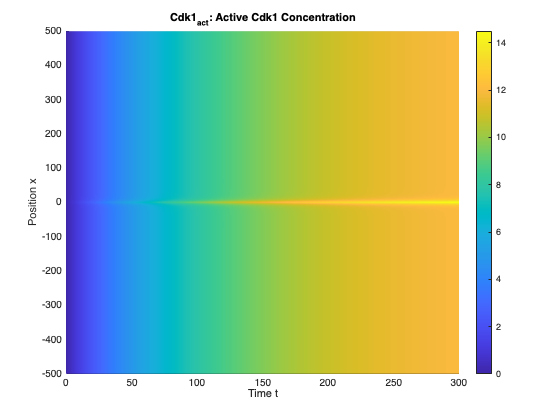

surf(tspan, xmesh(1501:2500), cdk1_act', cdk1_act', 'EdgeColor', 'none');
colorbar;
view(0, 90);
title('Cdk1_{act}: Active Cdk1 Concentration');
xlabel('Time t');
ylabel('Position x');

### ODE Model of Cdk1-APC/C Cell Cycle Oscillator

% sysnthesis rate in nM/min.
ode_params.ksynth =	1;

% rate params in min^-1.
ode_params.adeg	= 0.01;
ode_params.bdeg	= 0.04;
ode_params.acdc25 = 0.16;
ode_params.bcdc25 = 0.80;
ode_params.awee1 = 0.08;
ode_params.bwee1 = 0.40;

% Hill coefficients.
ode_params.ncdc25 = 11;
ode_params.nwee1 = 3.5;
ode_params.ndeg = 17;

% concentrations in nM.
ode_consts.EC50deg = 32;
ode_consts.EC50cdc25 = 35;
ode_consts.EC50wee1	= 30;

Solve the system of ODEs.

% time duration.
ode_consts.tmax = 500;

% initial Cdk1 and Cyclin concentrations are 0.
ode_consts.y_init = [0; 0];

% get ODE functions.
ode_funcs = cdk1_cyclin_ode;

% solve ODE.
[ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, ode_params, ode_consts), [0; ode_consts.tmax], ode_consts.y_init);

Unpack and Plot the ODE solutions.

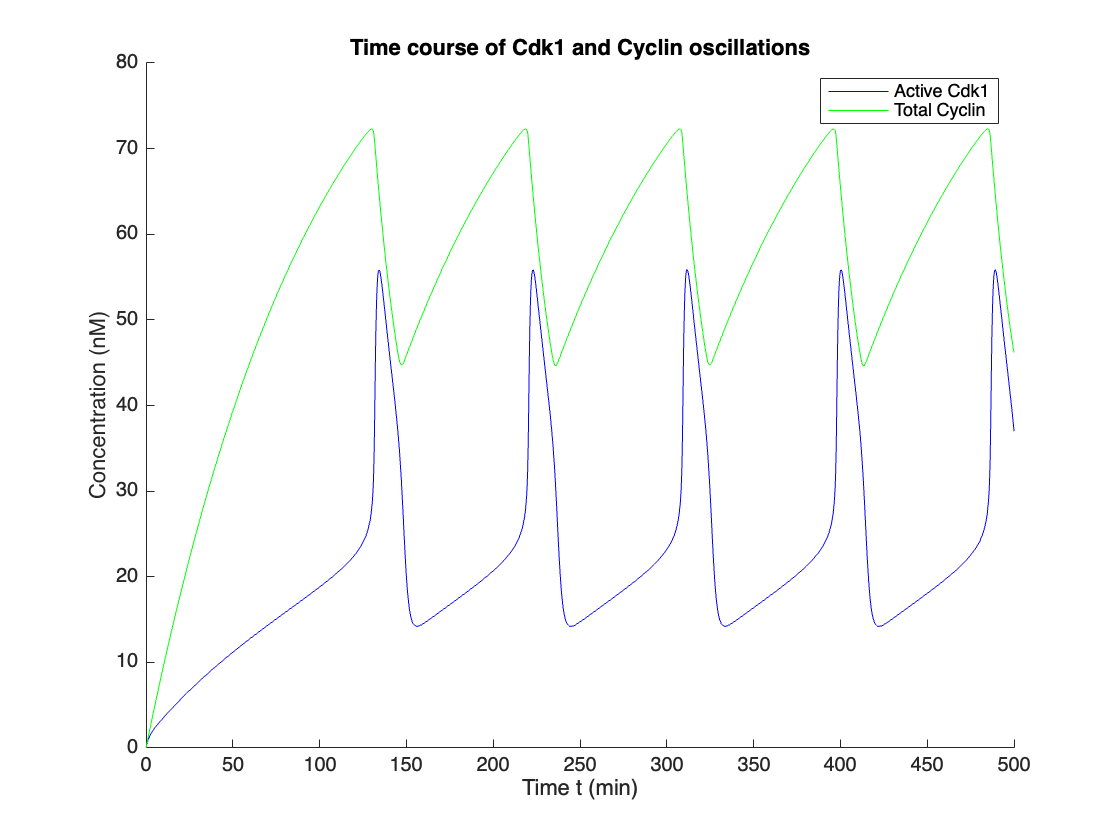

% unpack.
ode_cdk1 = x(:, 1);
ode_cyclin = x(:, 2);
% plot.
figure; hold on;
plot(ode_tout, ode_cdk1, 'Color', 'blue');
plot(ode_tout, ode_cyclin, 'Color', 'green');
title('Time course of Cdk1 and Cyclin oscillations');
xlabel('Time t (min)');
ylabel('Concentration (nM)');
legend('Active Cdk1', 'Total Cyclin');

Analytically solve the ODEs to obtain nullcline equations

[ode_cdk1_nullcline, ode_cyclin_nullcline] = ode_funcs.nullclines(ode_params, ode_consts)

$$cyclin\_eqn = 1-\mathrm{Cyc}\,\left(\frac{{{\mathrm{Cdk}}_{1}}^{17}}{25\,\left({{\mathrm{Cdk}}_{1}}^{17}+38685626227668133590597632\right)}+\frac{1}{100}\right)=0$$

ode_cdk1_nullcline = 0

$$ode\_cyclin\_nullcline = \frac{1}{\frac{{{\mathrm{Cdk}}_{1}}^{17}}{25\,\left({{\mathrm{Cdk}}_{1}}^{17}+38685626227668133590597632\right)}+\frac{1}{100}}$$

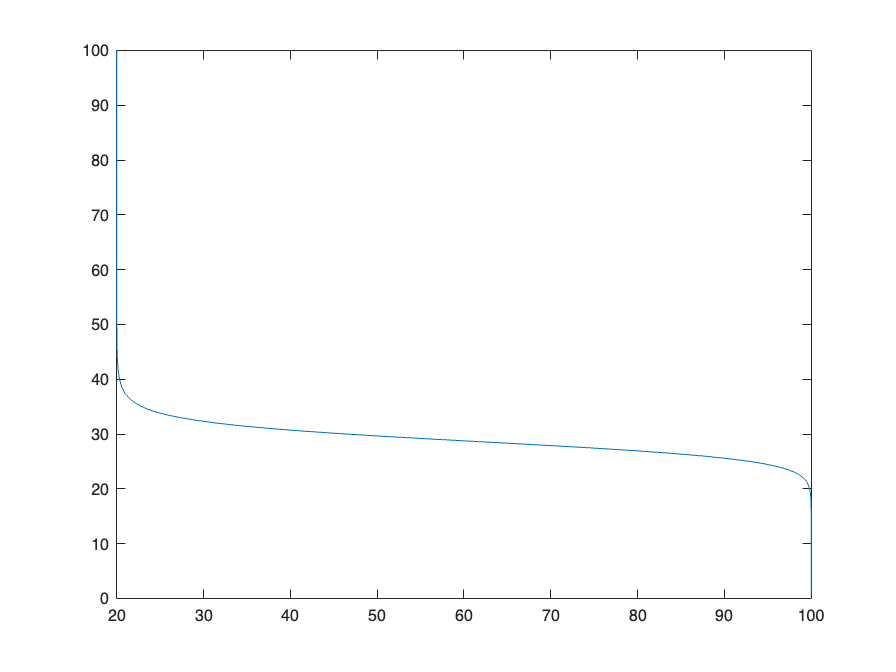

% var = vpasolve(cdk1_eqn,sym("Cdk1"))
figure;
plot(double(subs(ode_cyclin_nullcline, sym('Cdk1'), linspace(1, 100, 200))), 0.5:0.5:100)